# Velocity Distribution Function

First run the tracing program to get the cell `center. `

% ACTIVATEPLOT=false;
% folder="../asset/";
% baseName="order";
% Tracing

`or simply load the results from .mat files.`

folder="E:\Video Recordings\ball\aluminium\aluminium sweep_filling 55Hz 1.40\0725\";
load(folder+"/0.622/0.622_tracing.mat");
sampleSize=size(center,1);
sourceCount=size(center{1},1);

centerArray=zeros([sampleSize,sourceCount,2]);
velocity=zeros([sampleSize-1,sourceCount,2]);
centerArray(1,:,:)=center{1};
% FIXME: There might be NaNs, be careful about how to deal with them.
for i=2:sampleSize
    centerArray(i,:,:)=center{i};
    velocity(i-1,:,:)=centerArray(i,:,:)-centerArray(i-1,:,:); % unit in pixels.
end

Configure time interval and scaling.

frameRate=25;
dt=1/frameRate;
scaling=1; % unit: mm/pixel, remains to be calibrated.
centerArray=centerArray*scaling;
velocity=velocity*frameRate*scaling;

vx=velocity(:,:,1);
vy=velocity(:,:,2);
speed=arrayfun(@norm,vx,vy);

Let's first take a look into the velocity and speed distribution at certain instant.

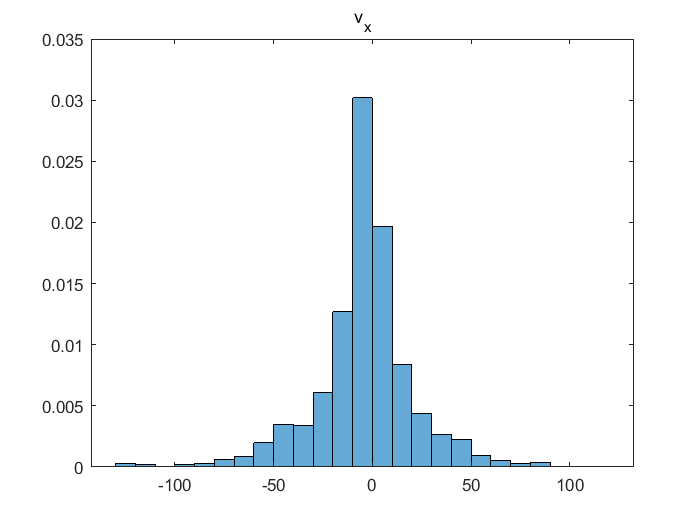

index=1;
figure;
histogram(vx(index,:),'Normalization','pdf');
title("v_x");

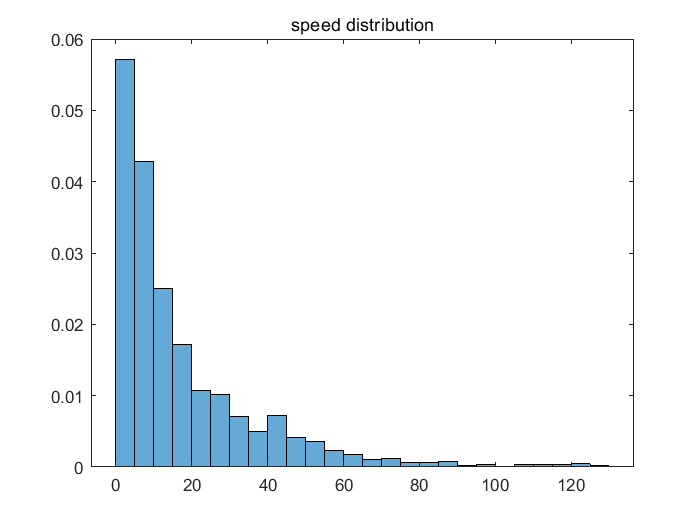

figure;
histogram(speed(index,:),'Normalization','pdf');
title("speed distribution");

To increase the population, combine all velocity in all instants together.

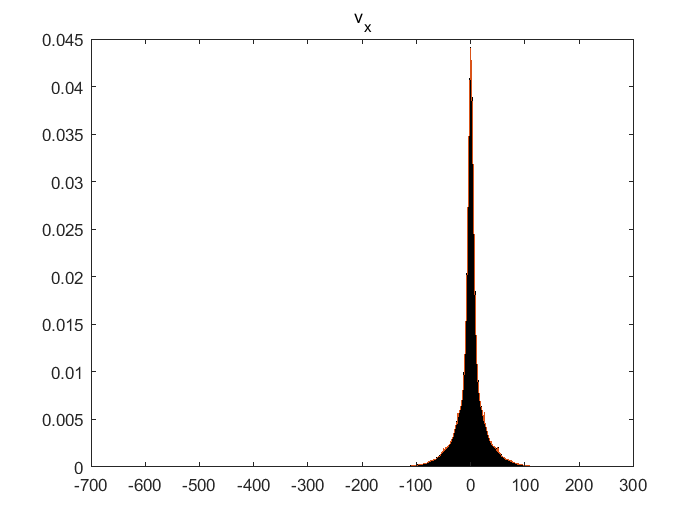

vxAll=reshape(vx,1,[]);
vyAll=reshape(vy,1,[]);
speedAll=arrayfun(@norm,vxAll,vyAll);
figure;
hV=histogram(vxAll,'Normalization','pdf');
PDVx=hV.Values;edgesV=hV.BinEdges; % probability density
hold on;
plot((edgesV(1:end-1)+edgesV(2:end))/2,PDVx); % locate at the center of bin.
title("v_x");

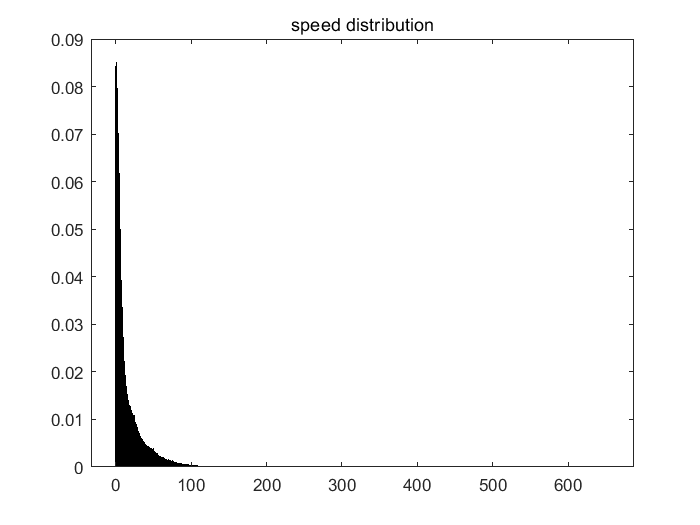

figure;
hS=histogram(speedAll,'Normalization','pdf');
hold on;
% [Ns,edgesS]=histcounts(speedAll,'Normalization','pdf');
Ns=hS.Values;edgesS=hS.BinEdges;
title("speed distribution");
hold off;

Fit and compare the distribution with Gaussian distribution.

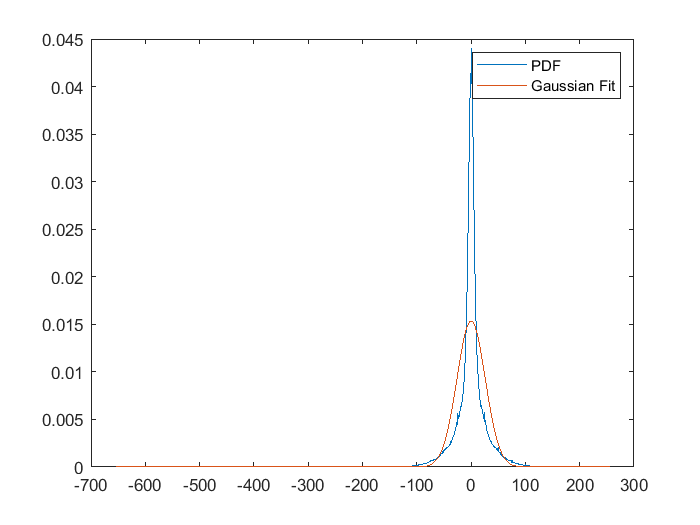

varVx=var(vxAll);
varVy=var(vyAll);
PDFitVx=fitdist(vxAll','Normal');
figure;
plot((edgesV(1:end-1)+edgesV(2:end))/2,PDVx,'DisplayName','PDF');
hold on;
plot(edgesV,PDFitVx.pdf(edgesV),'DisplayName','Gaussian Fit');
legend;

semilog plot

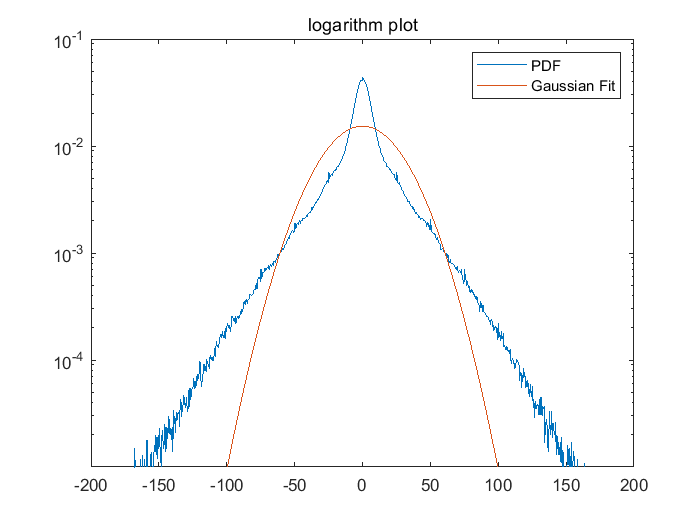

figure;
semilogy((edgesV(1:end-1)+edgesV(2:end))/2,PDVx,'DisplayName','PDF');
hold on;
semilogy(edgesV,PDFitVx.pdf(edgesV),'DisplayName','Gaussian Fit');
legend;
ylim([1e-5,1e-1]);
title("logarithm plot")
hold off;

Looks like an exponential decay on both sides...

Take a look at the spatial distribution of velocity.

index=100; % the index of the frame.
xSlice=centerArray(index,:,1);
ySlice=centerArray(index,:,2);
% FIXME: delaunay triangulation does not permit NaN.
tri=delaunay(xSlice,ySlice);
figure;
trisurf(tri,xSlice,ySlice,speed(index,:));

函数或变量 'speed' 无法识别。

colormap jet;
caxis([0,100*scaling]);
shading interp;
axis equal;
view([0,90]);

Maybe `scatter` is a better idea...

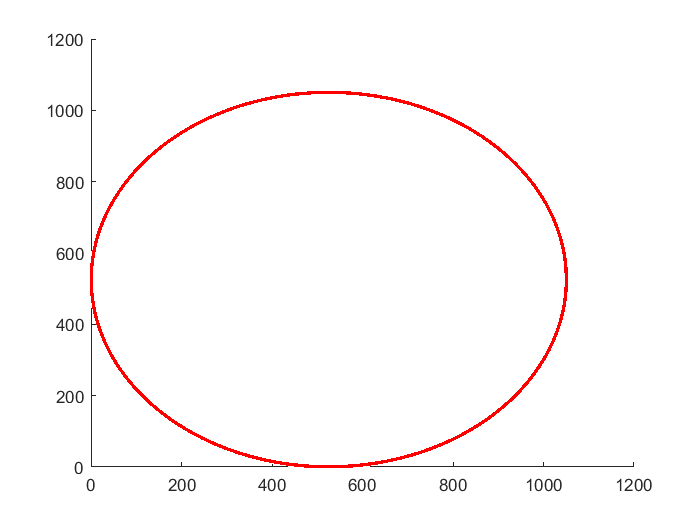

figure;
sidelength=1050/2;
viscircles([sidelength+0.5,sidelength+0.5],sidelength);
hold on;

scatter(xSlice,ySlice,16,speed(index,:),'filled');

函数或变量 'speed' 无法识别。

colormap jet;
caxis([0,100*scaling]);
axis equal;
hold off;

# Lindemann Ratio $\gamma_m$

i=500;
bondLength=cell(1,sampleSize);
for j=1:sampleSize
    try
        % FIXME: 1.NaNs 2.duplicate points
        DT=delaunayTriangulation(centerArray(j,:,1)',centerArray(j,:,2)');
    catch ME
        continue;
    end
    vertices=neighborVertices(DT,i);
%     for k=1:size
    bondLength{j}=arrayfun(@(id) norm(DT.Points(i,:)-DT.Points(id,:)),vertices);
    bondLength{j}=nonzeros(bondLength{j});
end
bondLengthMatrix=cell2mat(bondLength);

Awful things happen when the delaunay triangulation changes. Even the degree of a vertex could change. How do we arrange for bonds?

Or, simply calculate the variance of bond length...

# Bond-Orientational Order Parameter

frameIndex=1;
DT=delaunayTriangulation(centerArray(frameIndex,:,1)',centerArray(frameIndex,:,2)');
% accept id as a column vector.
orientationalOrder=@(id) mean(exp(1i*6*bondsOrientation(DT,id)),'omitnan');
psi6=arrayfun(orientationalOrder,1:size(DT.Points,1));

## Local bond-orientational order parameter

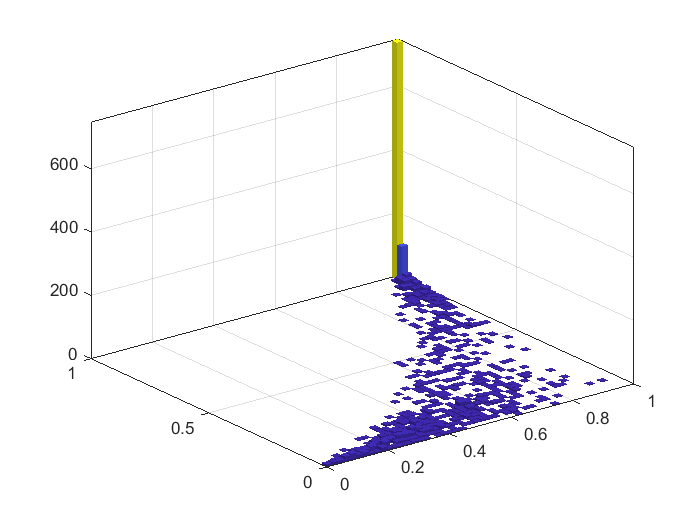

n6=arrayfun(@(id) mean(psi6(neighborVertices(DT,id)),'omitnan')*conj(psi6(id)),1:size(DT.Points,1));
figure;
h=histogram2(abs(psi6),abs(n6),50,'Normalization','pdf','ShowEmptyBins','off');
% colormap gray;
h.FaceColor='flat';

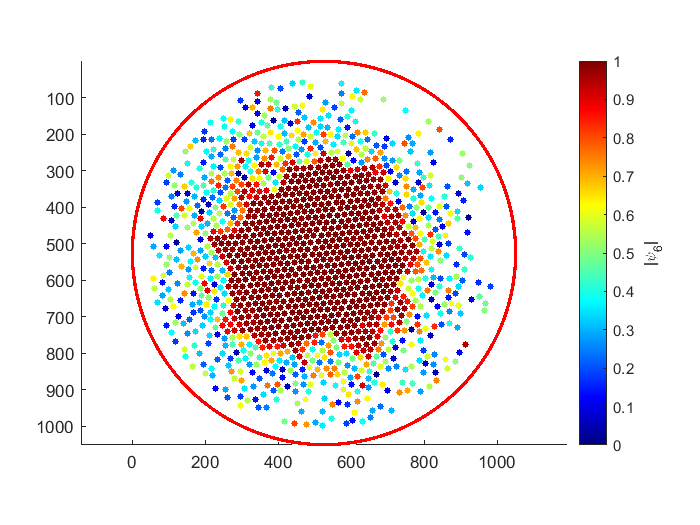

figure;
sidelength=1050/2;
viscircles([sidelength+0.5,sidelength+0.5],sidelength);
hold on;
scatter(centerArray(frameIndex,:,1),centerArray(frameIndex,:,2),16,abs(psi6),'filled');
axis ij;
axis equal;
caxis([0,1]);
bar=colorbar;
colormap jet;
bar.Label.String="|\psi_6|";

## Spatial correlation $g_6(r)$

centralPoint=reshape([525,525],[1,1,2]);
index=250;
radialDistance=vecnorm(centerArray(index,:,:)-centralPoint,2,3);
[sortedRadialDistance,sortIndex]=sort(radialDistance);
psi6_0R=psi6(sortIndex(1));
g_correlationR=real(psi6*conj(psi6_0R))./abs(psi6)/abs(psi6_0R);
g_correlationR_sorted=g_correlationR(sortIndex);

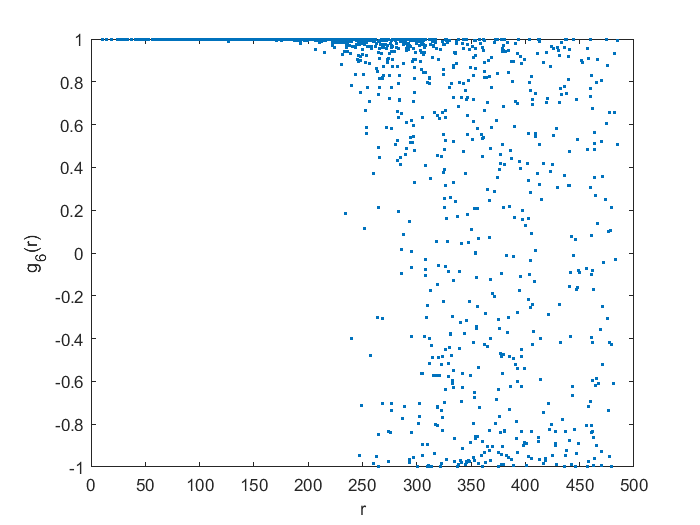

figure;
plot(sortedRadialDistance,g_correlationR_sorted,'.');
xlabel("r");
ylabel("g_6(r)");

## Global bond-orientational order parameter

psi6_global=zeros(1,sampleSize);
tic
for frameIndex=1:100:sampleSize
    try
        filteredCenter=centerArray(frameIndex,:,:);
        filteredCenter=filteredCenter(1,~isnan(filteredCenter(:,:,1)),:);
        DT=delaunayTriangulation(filteredCenter(1,:,1)',filteredCenter(1,:,2)');
    catch ME
        psi6_global(frameIndex)=nan;
        continue;
    end
    orientationalOrder=@(id) mean(exp(1i*6*bondsOrientation(DT,id)),'omitnan');
    psi6=arrayfun(orientationalOrder,1:size(DT.Points,1));
    psi6_global(frameIndex)=mean(psi6);
end

toc

历时 7.278382 秒。


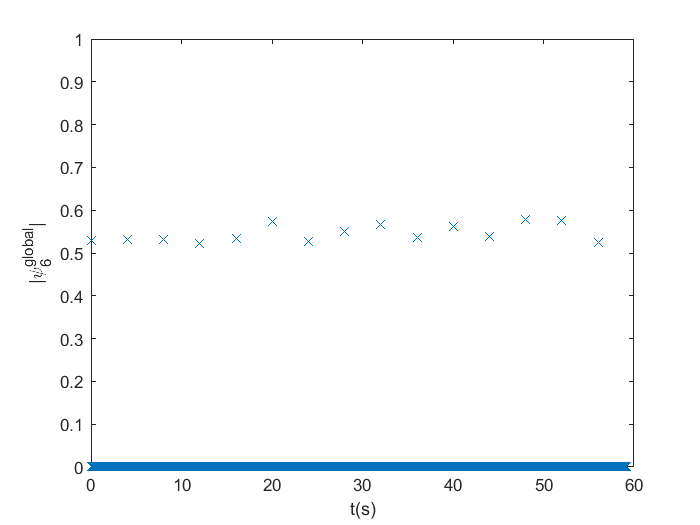

t=(1:sampleSize)*dt;
figure; 
plot(t,abs(psi6_global),'x');
xlabel("t(s)");
ylabel("|\psi_6^{global}|");
ylim([0,1]);

# Shape Factor

frameIndex=1;
DT=delaunayTriangulation(centerArray(frameIndex,:,1)',centerArray(frameIndex,:,2)');
[verticesVoronoi,regionsVoronoi]=DT.voronoiDiagram();

figure;
% scatter(verticesVoronoi(:,1),verticesVoronoi(:,2),4);
% hold on;
for i=1:size(verticesVoronoi,1)
    fill(verticesVoronoi(regionsVoronoi{i},1),verticesVoronoi(regionsVoronoi{i},2),rand([1,3]));
end
xlim([0,1050]);
ylim([0,1050]);
% hold off;

# Structure Factor

tic
index=1;
xArray=centerArray(index,:,1);
yArray=centerArray(index,:,2);
deltaX=xArray-xArray';
deltaY=yArray-yArray';
structureFactor=@(qx,qy)sum(exp(1i*(qx*deltaX+qy*deltaY)),'all');
granuleRadius=20; % unit: pixels. TODO: transform all units into universal mm.
qWindow=8/granuleRadius;
slices=40;
[qx,qy]=meshgrid(linspace(-qWindow,qWindow,slices));
SF=arrayfun(structureFactor,qx,qy);
toc

figure;
pcolor(qx,qy,abs(SF));
colormap jet;

The code above is too time consuming, despite the efforst on parallel design. This leads us to chase for more efficient way, which should utilize `fft`.

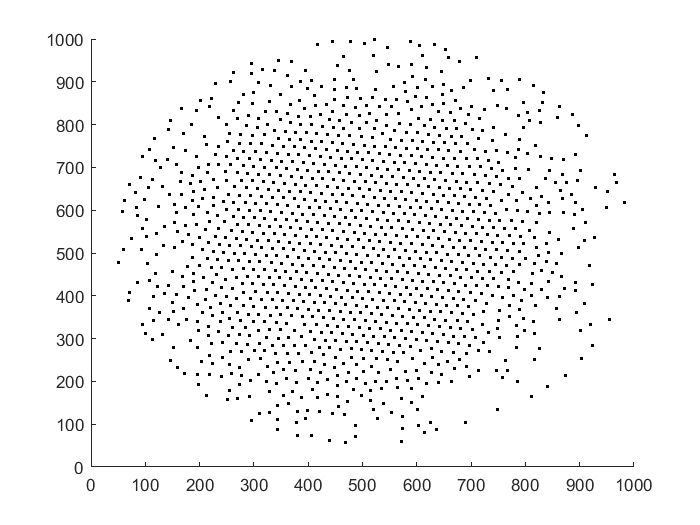

tic
figure('Color','w');
index=1;
xArray=centerArray(index,:,1);
yArray=centerArray(index,:,2);
scatter(xArray,yArray,4,'black','filled');

% set(gca,'color',[1,1,1]);
% plot(xArray,yArray,'k.','LineStyle','none','MarkerSize',4);
I_sum=NaN;
sidelength=1050/2;
limits=[-sidelength,sidelength];
axis([xArray(i)+limits,yArray(i)+limits]);

索引超出数组元素的数目(1362)。

axis off;
for i=1:sampleSize
    axis([xArray(i)+limits,yArray(i)+limits]);
    drawnow;
    frame=getframe(gcf);
    [I,~]=frame2im(frame);
    I=1-im2double(rgb2gray(I));
    I_fft=fftshift(fft2(I));
    if isnan(I_sum)
        I_sum=I_fft;
    else
        I_sum=I_sum+I_fft;
    end
end
toc

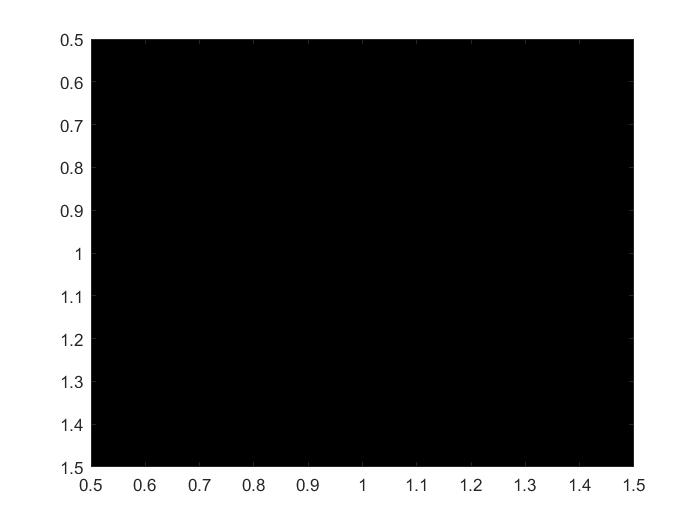

figure;
imagesc(abs(I_sum),[0,30]);
colormap gray;
shading interp;

# Mean Square Displacement

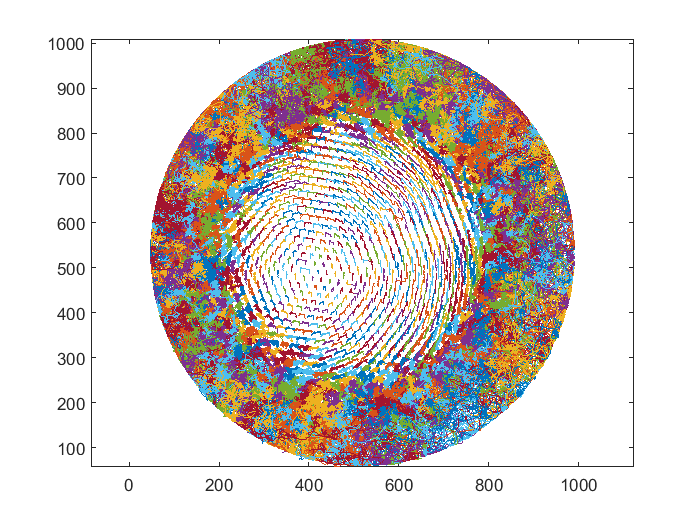

figure;
% nice and compact grammar!
plot(centerArray(:,:,1),centerArray(:,:,2));
axis equal;

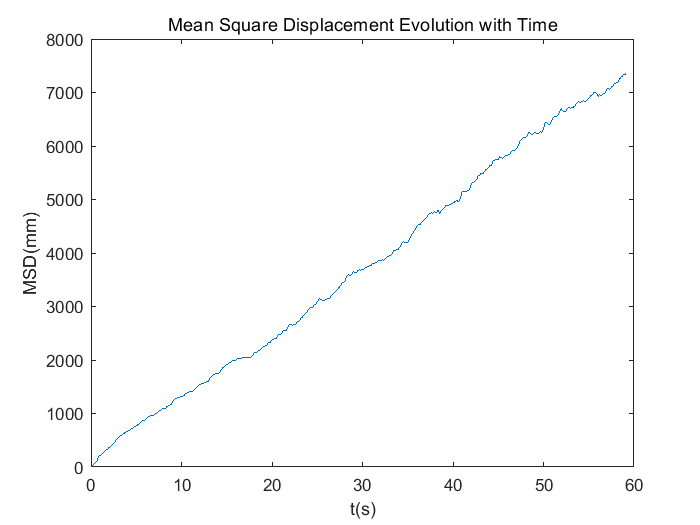

t=(0:sampleSize-1)*dt;
displacement=centerArray-centerArray(1,:,:);
SD=displacement(:,:,1).^2+displacement(:,:,2).^2;
MSD=mean(SD,2,'omitnan'); % omit nan, otherwise there would be discoutinutities.
figure;
plot(t,MSD);
ylabel("MSD(mm)");
xlabel("t(s)");
title("Mean Square Displacement Evolution with Time");

# Scattering Function

# Radial Distribution Function

index=1;
xArray=centerArray(index,:,1);
yArray=centerArray(index,:,2);
deltaX=xArray-xArray';
deltaY=yArray-yArray';
distance=sqrt(deltaX.^2+deltaY.^2); % symmetric matrix, only need the upper part of it.
distance=triu(distance);

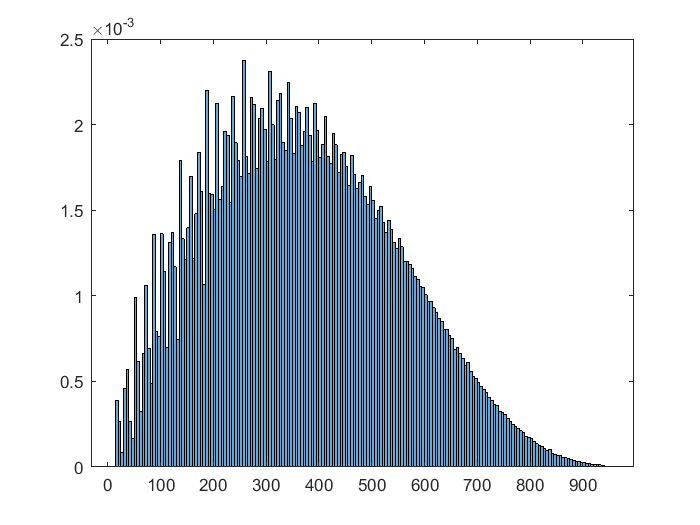

distanceList=nonzeros(distance);
figure;
h=histogram(distanceList,'Normalization','pdf');

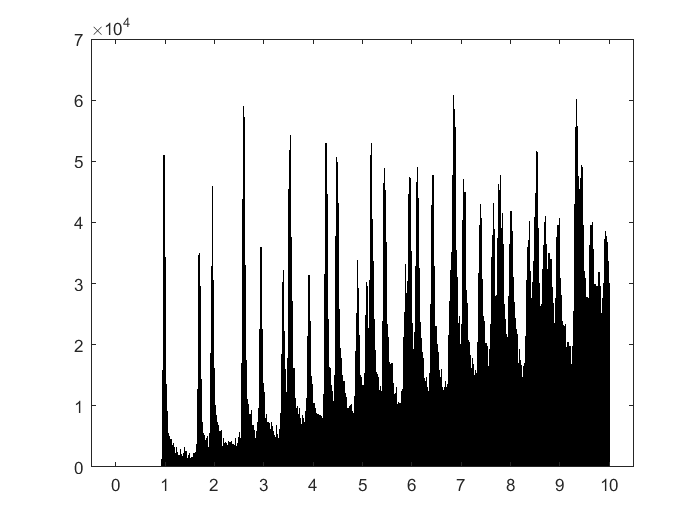

cutoff=200; % cutoff range.
radius=20; % unit is pixels.
step=radius/200;
distanceListCropped=distanceList(distanceList<cutoff);
distanceListNormalized=distanceListCropped/radius;
figure;
h=histogram(distanceListNormalized,(0:step:cutoff)/radius,'Normalization','countdensity');

N=h.Values;
binEdges=h.BinEdges;
binMids=(binEdges(1:end-1)+binEdges(2:end))/2;
% TODO: check the validity of this coefficients.
g=N/2./binMids*radius^2/sourceCount^2;

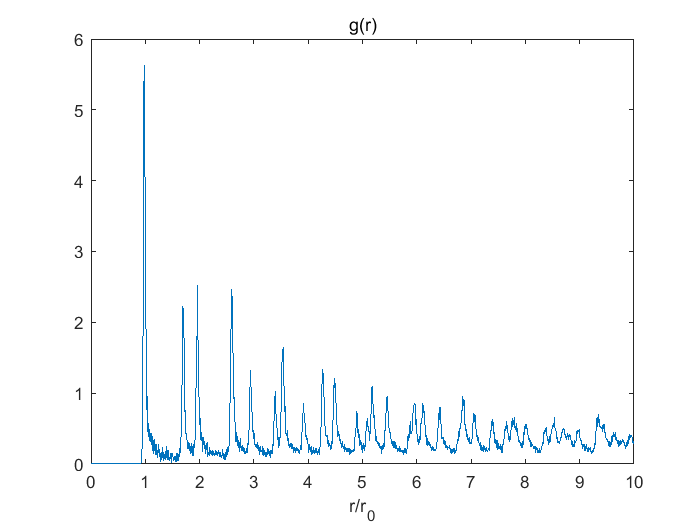

figure;
plot(binMids,g);
title("g(r)");
xlabel("r/r_{0}");

## Using $g(r=D)$ to illustrate phase transition

% batch
% extract filling ratio from fileName.
% folder="I:\Self Assembly\Video Recordings\ball\iron\4mm iron 140Hz 1.10 sweep_filling";
list=dir(folder+"/*.MOV");

fillingRatio=zeros(length(list),1);
for loop=1:length(list)
    temp=sscanf(list(loop).name,"%f");
    fillingRatio(loop)=temp(1);
end

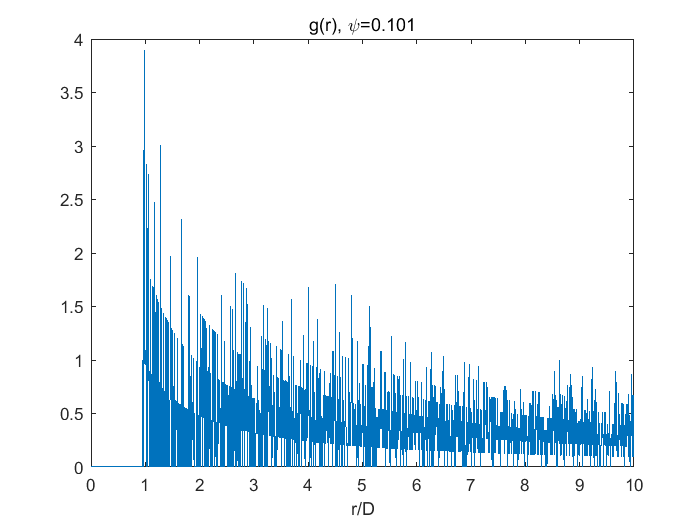

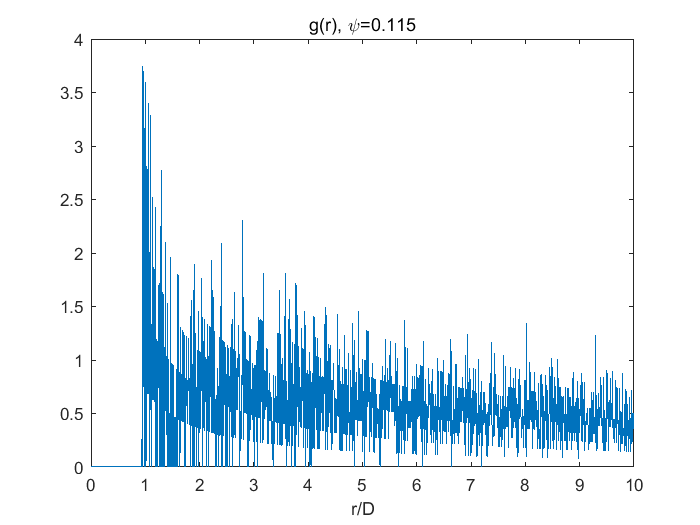

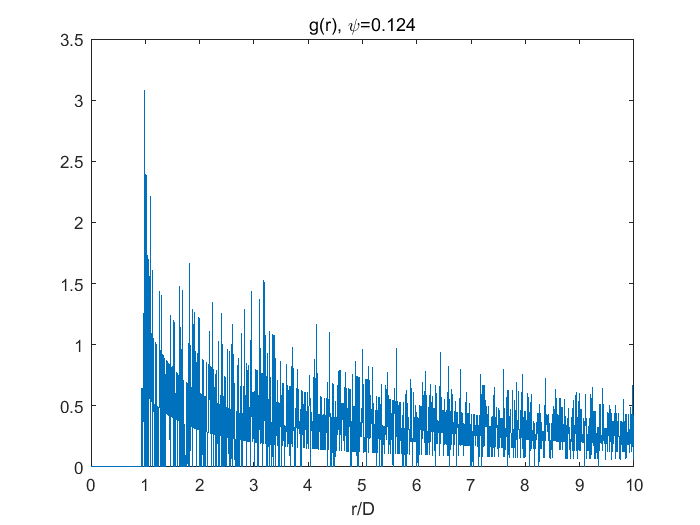

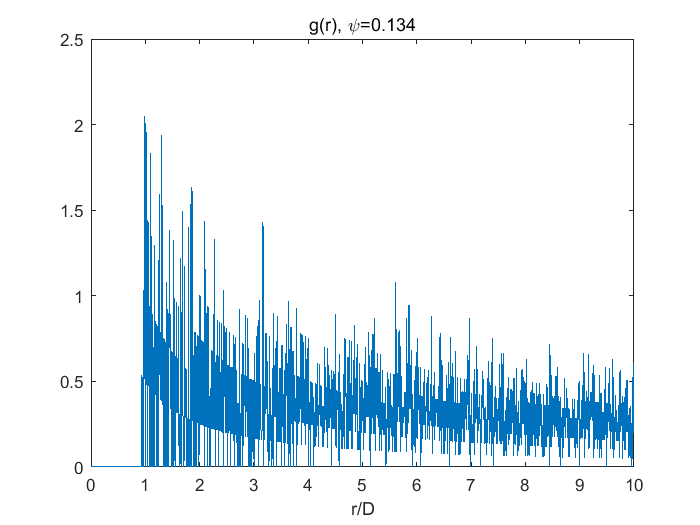

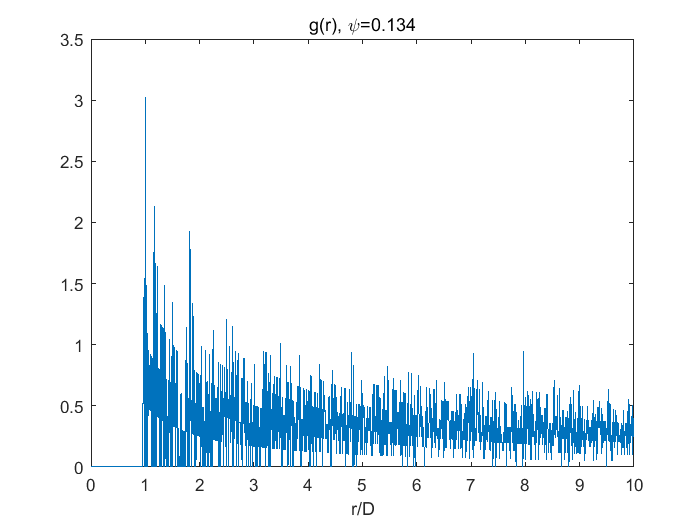

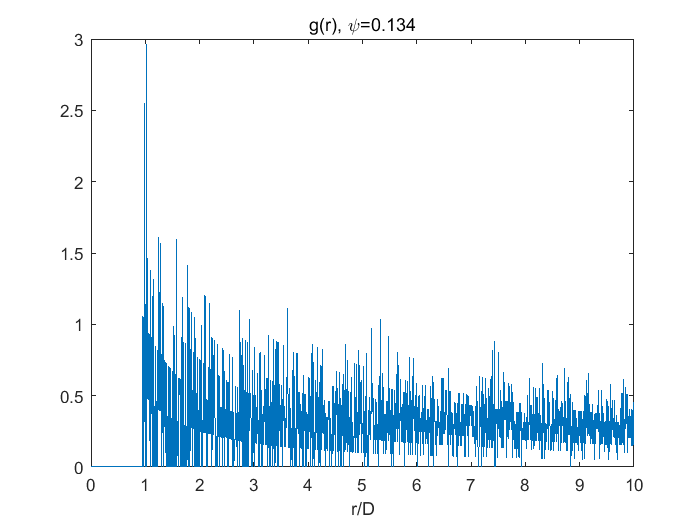

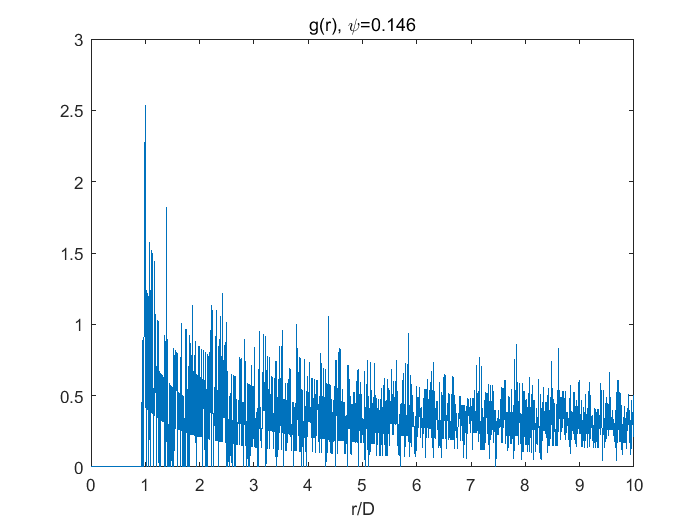

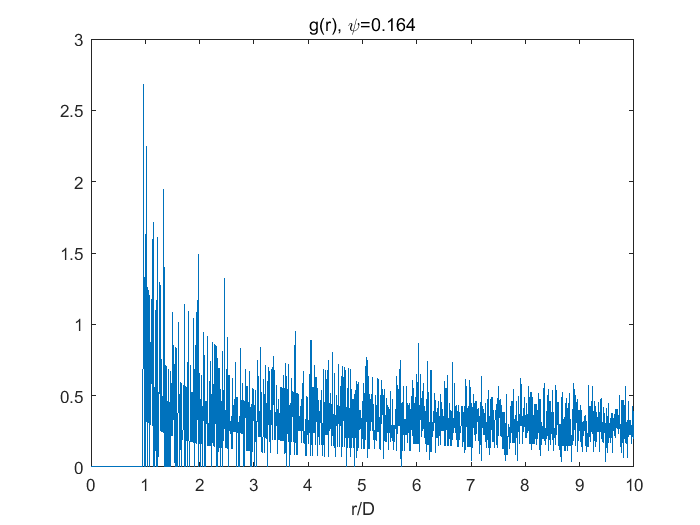

错误使用 load
无法读取文件 'E:\Video Recordings\ball\aluminium\aluminium sweep_filling 55Hz 1.40\0725\0.586_clip\0.586_clip_tracing.mat'。没有此类文件或目录。

index=200;
g_1D=zeros(length(list),1);
for loop=1:length(list)
    fileName=list(loop).name;
    temp=split(fileName,'.');
    extName=temp(end);
    baseName=erase(fileName,"."+extName);
    load(list(loop).folder+"/"+baseName+"/"+baseName+"_tracing.mat");
    sourceCount=size(center{1},1);
% basically copying the codes above.
xArray=center{index}(:,1);
yArray=center{index}(:,2);
deltaX=xArray-xArray';
deltaY=yArray-yArray';
distance=sqrt(deltaX.^2+deltaY.^2); % symmetric matrix, only need the upper part of it.
distance=triu(distance);
distanceList=nonzeros(distance);
cutoff=200; % cutoff range.
radius=20; % unit is pixels.
step=radius/200;
distanceListCropped=distanceList(distanceList<cutoff);
distanceListNormalized=distanceListCropped/radius;
figure;
[N,binEdges]=histcounts(distanceListNormalized,(0:step:cutoff)/radius,'Normalization','countdensity');
binMids=(binEdges(1:end-1)+binEdges(2:end))/2;
% TODO: check the validity of this coefficients.
g=N/2./binMids*radius^2/sourceCount^2;
figure;
plot(binMids,g);
title(sprintf("g(r), \\psi=%.3f",fillingRatio(loop)));
xlabel("r/D");
g_1D(loop)=max(g); 
end

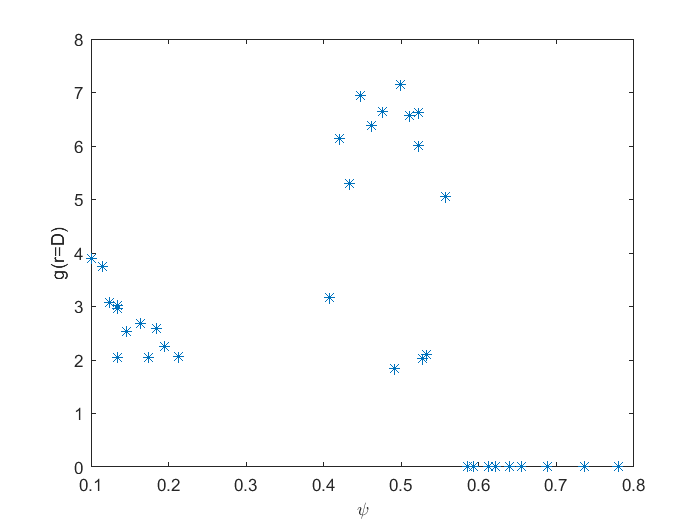

figure;
plot(fillingRatio,g_1D,'*');
xlabel("\psi");
ylabel("g(r=D)");